# Práctica 6: Máscaras de convolución para la detección de bordes

**Creación de las máscaras**

Prewittx = [-1 0 1;-1 0 1;-1 0 1];
Prewitty= [1 1 1; 0 0 0; -1 -1 -1];
Sobelx= [-1 0 1; -2 0 2; -1 0 1];
sobely= [-1 -2 -1; 0 0 0; 1 2 1];

## Tomagrafía corte transversal

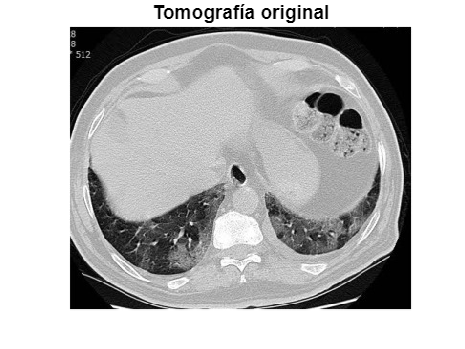

%Cargar imagen
tac = imread("tac_imagen.jpg");
figure;

tac_rgb = rgb2gray(tac);
imshow(tac_rgb);
title('Tomografía original')

**Aplicación de Prewitt**

NuevaXP = conv2(tac_rgb,Prewittx);
NuevaYP = conv2(tac_rgb,Prewitty);
Imagen_nuevaP = NuevaYP + NuevaXP;

figure;
subplot(2, 2, 1);
imshow(Imagen_nuevaP);
title('TAC filt. - máscara Prewitt')

subplot(2, 2, 2);
Imagen_nuevaP = mat2gray(Imagen_nuevaP);
imshow(Imagen_nuevaP);
title('TAC filt. - máscara Prewitt normalizada')

**Aplicación de Sobel en mastografía**

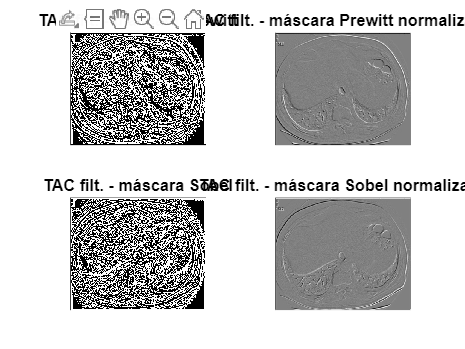

NuevaXS = conv2(tac_rgb,Sobelx);
NuevaYS = conv2(tac_rgb,sobely);
Imagen_nuevaS= NuevaYS + NuevaXS;

subplot(2, 2, 3);
imshow(Imagen_nuevaS);
title('TAC filt. - máscara Sobel')
Imagen_nuevaS = mat2gray(Imagen_nuevaS);

subplot(2, 2, 4);
imshow(Imagen_nuevaS);
title('TAC filt. - máscara Sobel normalizada')

## Radiografía lateral cráneo

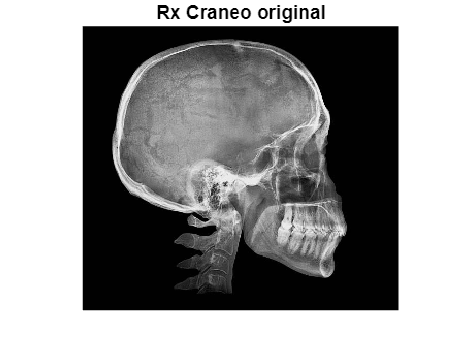

%Cargar imagen
rxcreano = imread("rxcraneo_imagen.jpg");
figure;

rxcreano_rgb = rgb2gray(rxcreano);
imshow(rxcreano_rgb);
title('Rx Craneo original')

**Aplicación de Prewitt**

NuevaXP = conv2(rxcreano_rgb,Prewittx);
NuevaYP = conv2(rxcreano_rgb,Prewitty);
Imagen_nuevaP = NuevaYP + NuevaXP;

figure;
subplot(2, 2, 1);
imshow(Imagen_nuevaP);
title('Rx Craneo filt. - máscara Prewitt')

subplot(2, 2, 2);
Imagen_nuevaP = mat2gray(Imagen_nuevaP);
imshow(Imagen_nuevaP);
title('Rx Craneo filt. - máscara Prewitt normalizada')

**Aplicación de Sobel en mastografía**

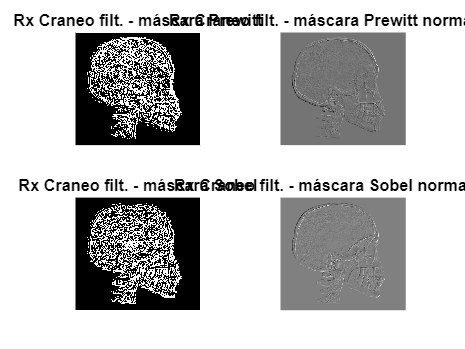

NuevaXS = conv2(rxcreano_rgb,Sobelx);
NuevaYS = conv2(rxcreano_rgb,sobely);
Imagen_nuevaS= NuevaYS + NuevaXS;

subplot(2, 2, 3);
imshow(Imagen_nuevaS);
title('Rx Craneo filt. - máscara Sobel')
Imagen_nuevaS = mat2gray(Imagen_nuevaS);

subplot(2, 2, 4);
imshow(Imagen_nuevaS);
title('Rx Craneo filt. - máscara Sobel normalizada')